# 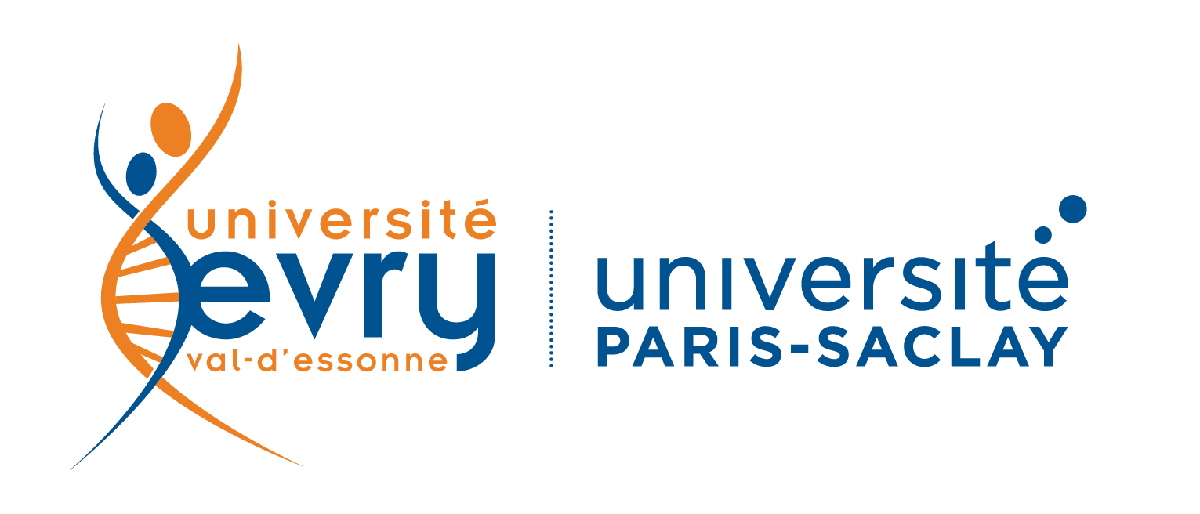

# **M2 E3A SAAS- Flight Modeling and Control**

## **Université d'Évry Paris-Saclay**

**Made by:** Minota Matewos DACHE,  **ID:** 20235671

**Email: **minotadache@gmail.com

## Linear and Nonlinear longitudinal and lateral control 

%sim("QuadrotorModel.slx");
figure;
plot3(out.ref(:,1),out.ref(:,2),out.ref(:,3),'r-.',LineWidth=1.5);
hold on
plot3(out.S(:,1),out.S(:,2),out.S(:,3),'b',LineWidth=1.5);
grid on 
%title('zero reference linear control')
title('Constant reference linear control(z=1m)')
%title('Constant Trajectory')
legend('Measurement','Reference')

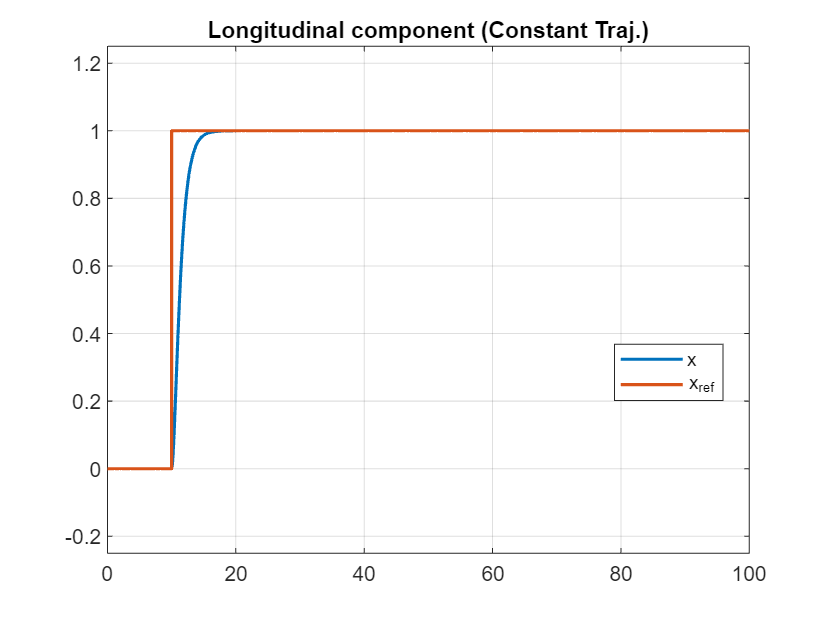

figure;
plot(out.tout,out.S(:,1),LineWidth=1.5)
hold on 
plot(out.tout,out.ref(:,1),LineWidth=1.5)
legend('x','x_{ref}',Location='best')
axis([0 100,-0.25 1.25])
title('Longitudinal component (Constant Traj.)')
% title('Longitudinal component (Variable Traj.)')
% axis([0 180,-1.25  1.25])
grid on

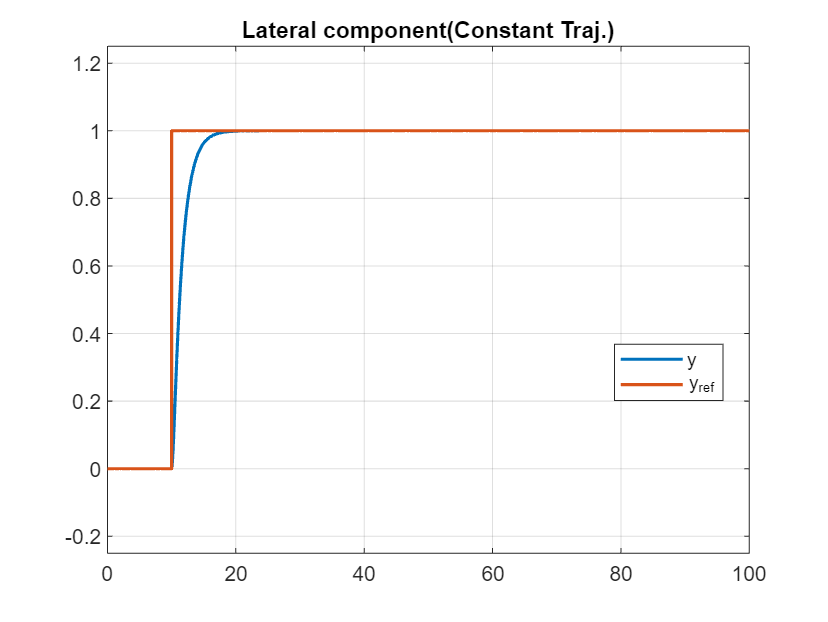

figure;
plot(out.tout,out.S(:,2),LineWidth=1.5)
hold on 
plot(out.tout,out.ref(:,2),LineWidth=1.5)
legend('y','y_{ref}',Location='best')
axis([0 100,-0.25  1.25])
title('Lateral component(Constant Traj.)')

% title('Lateral component(Variable Traj.)')
% axis([0 180,-1.25  1.25])
grid on

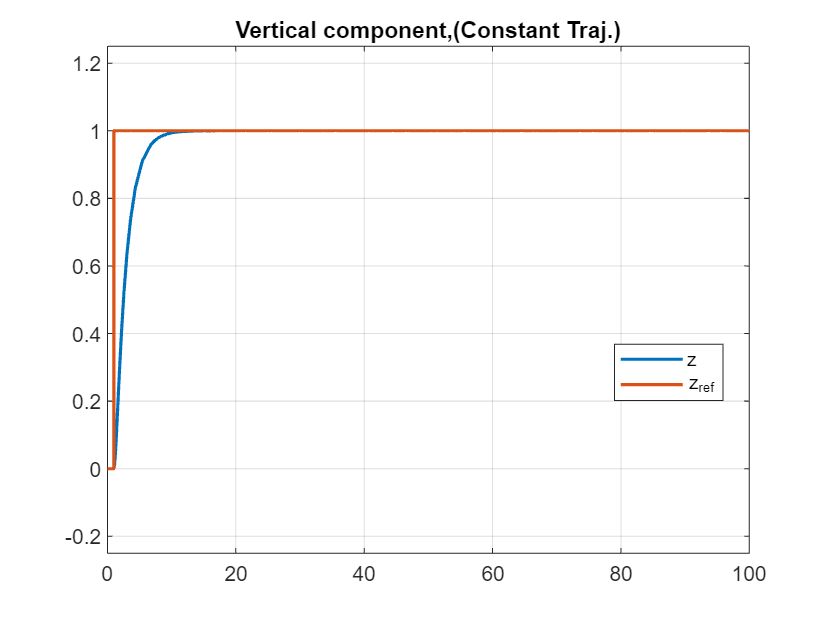

figure; 
plot(out.tout,out.S(:,3),LineWidth=1.5)
hold on 
plot(out.tout,out.ref(:,3),LineWidth=1.5)
axis([0 100,-0.25  1.25])
legend('z','z_{ref}', Location='best')
title('Vertical component,(Constant Traj.)')
grid on